# H4

Es vol tenir una útil aplicació de visió per computador que compti pedretes en la sorra. Amb aquest objectiu caldrà crear una aplicació que compti el numero de pedretes que hi en la imatge i que tinguin unes mides entre un cert màxim i mínim a determinar per l’usuari. La definició de mida d’una pedreta és lliure i caldrà que la definiu vosaltres mateixos. Mostreu el resultat fent una superposició de les pedretes segmentades sobre la imatge original.

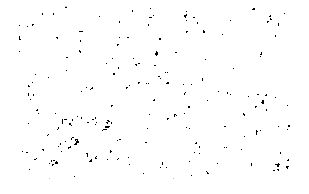

I = rgb2gray(imread('pedres.jpg'));
%imshow(I);

I = medfilt2(I,[3 3]);
llindar = graythresh(I)*256;
BW = I > llindar;
BW = imopen(BW,strel("square",3));
%imshow(BW);

TD = -bwdist(not(BW),"quasi-euclidean");
TD = medfilt2(TD,[15 15]);
%imshow(TD,[]);

TD(not(BW)) = -Inf;  % per evitar la propagació de l'aigua en el Background
WS = watershed(TD);

objetos = bwconncomp(WS);

% Obtener las propiedades de las regiones
propiedades = regionprops(objetos, 'Area');

% Definir el tamaño mínimo y máximo de los objetos a mostrar
tam_min = 0; % Tamaño mínimo
tam_max = 100; % Tamaño máximo

% Crear una nueva matriz de etiquetas que sólo incluya objetos de tamaño adecuado
WS_nuevo = WS;
for i = 1:objetos.NumObjects
    if propiedades(i).Area < tam_min || propiedades(i).Area > tam_max
        WS_nuevo(objetos.PixelIdxList{i}) = 0;
    end
end

% Crear la imagen final mostrando sólo los objetos de tamaño adecuado
IB = WS_nuevo == 0;
imshow(IB);


RGB3 = imoverlay(I,IB);
%imshow(RGB2);

% Contar los objetos que cumplen con los criterios de tamaño
contador = 0;
for i = 1:objetos.NumObjects
    if propiedades(i).Area > tam_min && propiedades(i).Area < tam_max
        contador = contador + 1;
    end
end

fprintf('Hay %d objetos de tamaño entre %d y %d píxeles en la imagen.\n', contador, tam_min, tam_max);

Hay 329 objetos de tamaño entre 0 y 100 píxeles en la imagen.


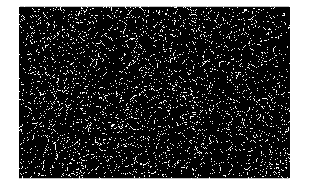


IB2 = WS == 0;
imshow(IB2);

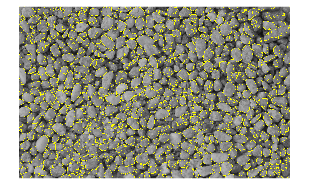


RGB2 = imoverlay(I,IB2);
%montage({IB,IB2});
%montage({RGB2,RGB3});
imshow(RGB2);